kerr_MHz = -0.4; 
kappa_int_MHz = 0.4;
kappa_ext_MHz = 1.2;
kappa_tot_MHz = kappa_ext_MHz + kappa_int_MHz;
epsilon_drive_MHz = 1.5*kappa_tot_MHz;
detunings_MHz = linspace(-6*kappa_tot_MHz, 6*kappa_tot_MHz, 121);

kappa_tot = kappa_tot_MHz*1e6;
kappa_int = kappa_int_MHz*1e6;
kappa_ext = kappa_ext_MHz*1e6;
detunings = detunings_MHz*1e6;
epsilon_drive = epsilon_drive_MHz*1e6;
kerr = kerr_MHz*1e6;

roots= zeros(length(detunings), 5);
stability = zeros(length(detunings), 5);
stability(:,4:5) = 0;
stability_finder = zeros(length(detunings),1);
stability_finder(detunings > -sqrt(epsilon_drive^2 - kappa_tot^2/4)) = 1;
stability_finder(detunings < -sqrt(epsilon_drive^2 - kappa_tot^2/4)) = 2;
stability(:, 2) = stability_finder;
stability(:, 3) = stability_finder;
stability_finder(detunings > sqrt(epsilon_drive^2 - kappa_tot^2/4)) = 0;
stability(:,1) = abs(1 - stability_finder);
stability_finder(detunings < sqrt(epsilon_drive^2 - kappa_tot^2/4)) = 2;
stability(:, 4) = stability_finder;
stability(:, 5) = stability_finder;

roots(:,1) = 0; 
roots(:, 2) = (-detunings - sqrt(epsilon_drive^2 - kappa_tot^2/4))/kerr;
roots(:, 3) = -(-detunings - sqrt(epsilon_drive^2 - kappa_tot^2/4))/kerr;
roots(:, 4) = (-detunings + sqrt(epsilon_drive^2 - kappa_tot^2/4))/kerr;
roots(:, 5) = -(-detunings + sqrt(epsilon_drive^2 - kappa_tot^2/4))/kerr;

roots(~isreal(roots)) = NaN;

root_1 = roots(:,1);
root_2 = roots(:,2);
root_3 = roots(:,3);
root_4 = roots(:,4);
root_5 = roots(:,5);

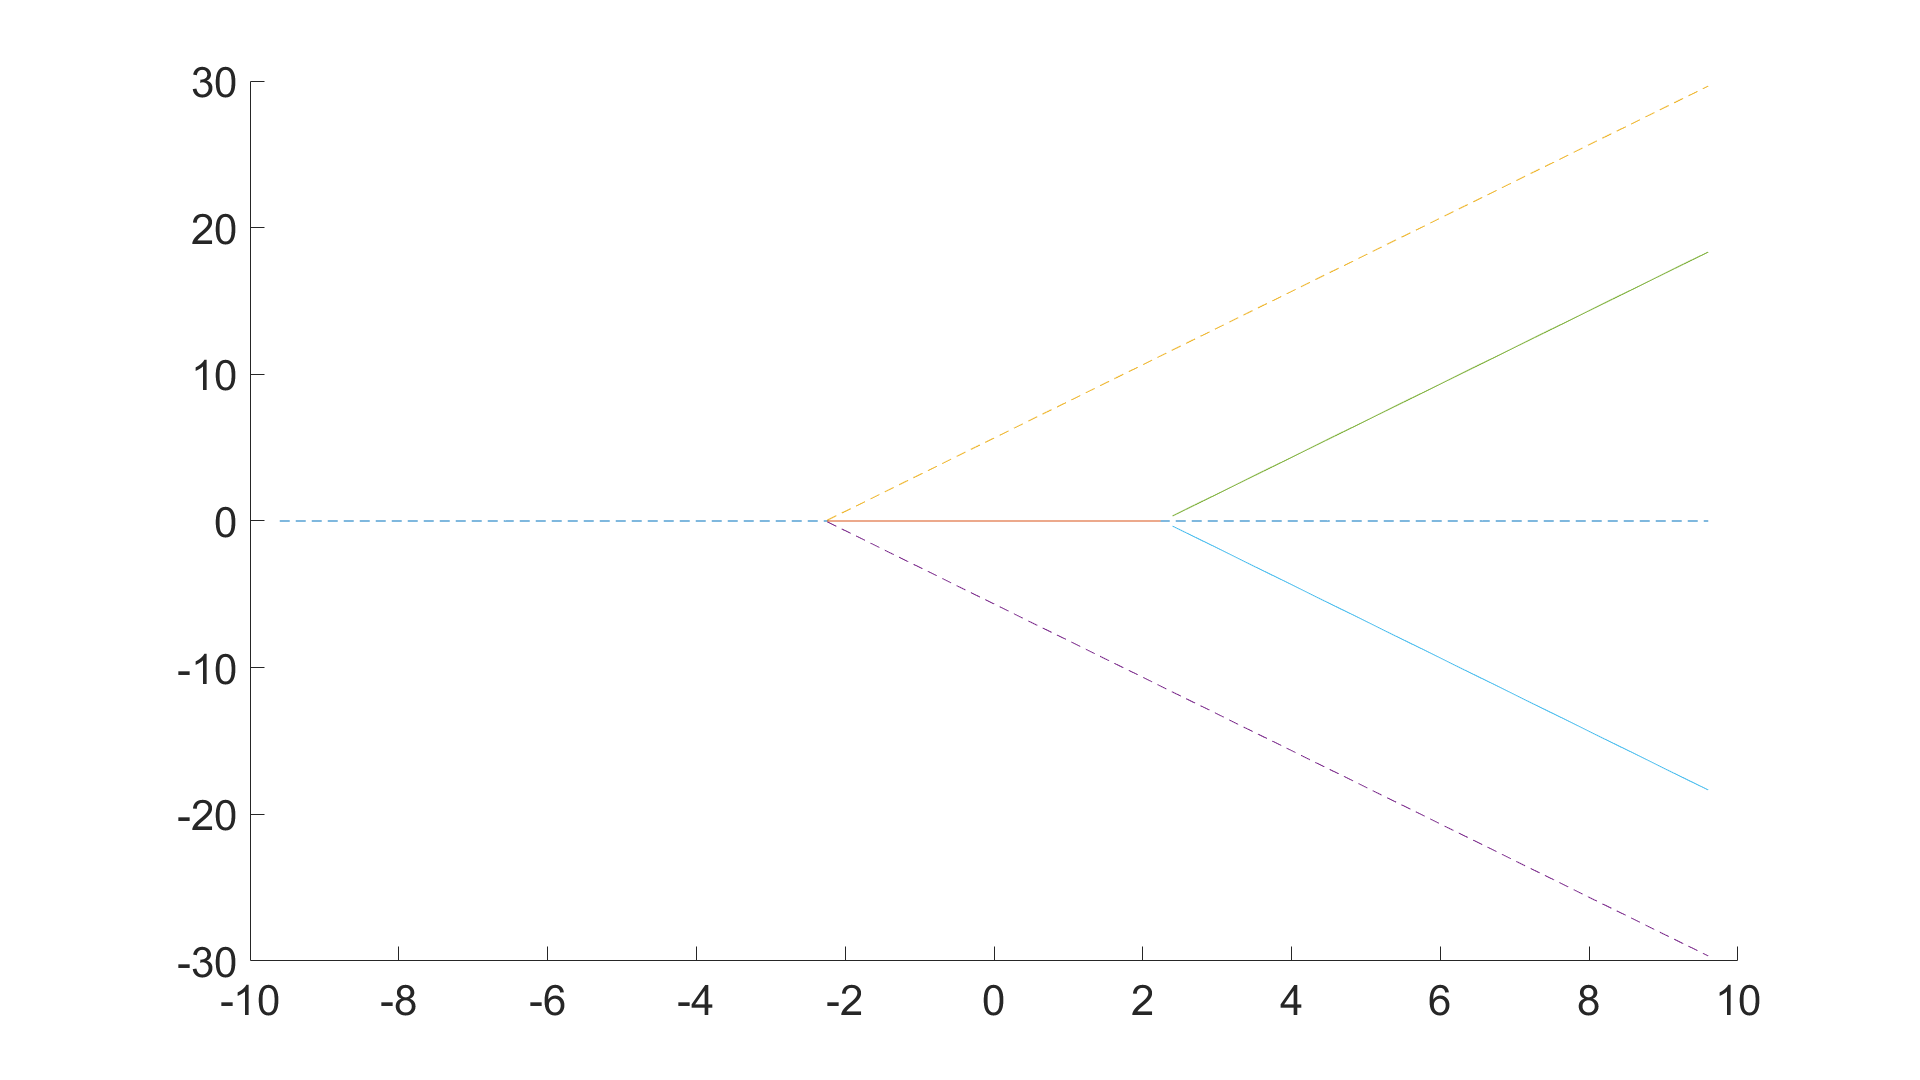

figure
hold on
plot(detunings_MHz(squeeze(stability(:,1)) == 1), root_1(squeeze(stability(:,1) == 1)), '--')
plot(detunings_MHz(squeeze(stability(:,1)) == 0), root_1(squeeze(stability(:,1) == 0)))

plot(detunings_MHz(squeeze(stability(:,2)) == 1), root_2(squeeze(stability(:,2) == 1)), '--')
plot(detunings_MHz(squeeze(stability(:,2)) == 0), root_2(squeeze(stability(:,2) == 0)))

plot(detunings_MHz(squeeze(stability(:,3)) == 1), root_3(squeeze(stability(:,3) == 1)), '--')
plot(detunings_MHz(squeeze(stability(:,3)) == 0), root_3(squeeze(stability(:,3) == 0)))

plot(detunings_MHz(squeeze(stability(:,4)) == 1), root_4(squeeze(stability(:,4) == 1)), '--')
plot(detunings_MHz(squeeze(stability(:,4)) == 0), root_4(squeeze(stability(:,4) == 0)))

plot(detunings_MHz(squeeze(stability(:,5)) == 1), root_5(squeeze(stability(:,5) == 1)), '--')
plot(detunings_MHz(squeeze(stability(:,5)) == 0), root_5(squeeze(stability(:,5) == 0)))